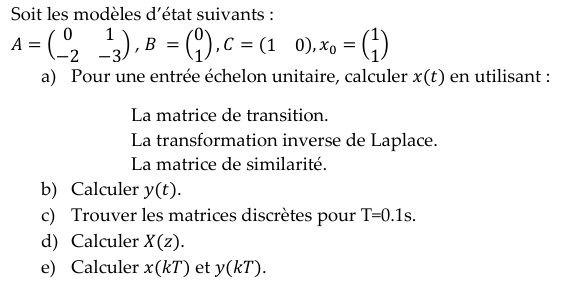

a) Calcul de 𝒙(𝒕) en utilisant la matrice de transition 

A=[0 1;-2 -3]; B=[0;1];C=[1 0];x0=[1;1];u=1;
syms s t tau
s*eye(2)-A

$$ans = \left(\begin{array}{cc} s & -1\\ 2 & s+3 \end{array}\right)$$

% ans =
% [ s, -1]
% [ 2, s + 3]

inv(s*eye(2)-A)

$$ans = \left(\begin{array}{cc} \frac{s+3}{s^{2}+3\,s+2} & \frac{1}{s^{2}+3\,s+2}\\ -\frac{2}{s^{2}+3\,s+2} & \frac{s}{s^{2}+3\,s+2} \end{array}\right)$$

% ans =
% [ (s + 3)/(s^2 + 3*s + 2) , 1/(s^2 + 3*s + 2)]
% [ -2/(s^2 + 3*s + 2) , s/(s^2 + 3*s + 2)]
phi=ilaplace(inv(s*eye(2)-A))

$$phi = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}\\ 2\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-2\,t}-{\mathrm{e}}^{-t} \end{array}\right)$$

% phi = [ 2*exp(-t) - exp(-2*t) , exp(-t) - exp(-2*t)]
% [ 2*exp(-2*t) - 2*exp(-t) , 2*exp(-2*t) - exp(-t)]
phi_tau=ilaplace(inv(s*eye(2)-A),t-tau)

$$phi\_tau = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{\tau -t}-{\mathrm{e}}^{2\,\tau -2\,t} & {\mathrm{e}}^{\tau -t}-{\mathrm{e}}^{2\,\tau -2\,t}\\ 2\,{\mathrm{e}}^{2\,\tau -2\,t}-2\,{\mathrm{e}}^{\tau -t} & 2\,{\mathrm{e}}^{2\,\tau -2\,t}-{\mathrm{e}}^{\tau -t} \end{array}\right)$$

% phi_tau = [2*exp(tau - t) - exp(2*tau - 2*t) , exp(tau - t) -exp(2*tau - 2*t)]
% [2*exp(2*tau-2*t) - 2*exp(tau - t) , 2*exp(2*tau -2*t) - exp(tau - t)]
X=phi*x0+int(phi_tau*B*u,tau,0,t)

$$X = \left(\begin{array}{c} 3\,{\mathrm{e}}^{-t}-2\,{\mathrm{e}}^{-2\,t}+\frac{{\mathrm{e}}^{-2\,t}\,{\left({\mathrm{e}}^{t}-1\right)}^{2}}{2}\\ 4\,{\mathrm{e}}^{-2\,t}-3\,{\mathrm{e}}^{-t}+{\mathrm{e}}^{-2\,t}\,\left({\mathrm{e}}^{t}-1\right) \end{array}\right)$$

% x = 2*exp(-t) - (3*exp(-2*t))/2 + 1/2
% -exp(-2*t)*(2*exp(t) - 3)
y=C*X

$$y = 3\,{\mathrm{e}}^{-t}-2\,{\mathrm{e}}^{-2\,t}+\frac{{\mathrm{e}}^{-2\,t}\,{\left({\mathrm{e}}^{t}-1\right)}^{2}}{2}$$

% y = 2*exp(-t) - (3*exp(-2*t))/2 + 1/2


b) Calcul de 𝒙(𝒕) en utilisant la transformation inverse de Laplace :

A=[0 1;-2 -3]; B=[0;1];C=[1 0];x0=[1;1];u=1;
syms s
U=1/s;
s*eye(2)-A;
inv(s*eye(2)-A)

$$ans = \left(\begin{array}{cc} \frac{s+3}{s^{2}+3\,s+2} & \frac{1}{s^{2}+3\,s+2}\\ -\frac{2}{s^{2}+3\,s+2} & \frac{s}{s^{2}+3\,s+2} \end{array}\right)$$

% ans = [ (s + 3)/(s^2 + 3*s + 2) , 1/(s^2 + 3*s + 2)]
% [ -2/(s^2 + 3*s + 2) , s/(s^2 + 3*s + 2)]
X=inv(s*eye(2)-A)*x0+inv(s*eye(2)-A)*B*U

$$X = \left(\begin{array}{c} \frac{1}{s^{2}+3\,s+2}+\frac{s+3}{s^{2}+3\,s+2}+\frac{1}{s\,\left(s^{2}+3\,s+2\right)}\\ \frac{s}{s^{2}+3\,s+2}-\frac{1}{s^{2}+3\,s+2} \end{array}\right)$$

% X =
% 1/(s^2 + 3*s + 2) + (s + 3)/(s^2 + 3*s + 2) + 1/(s*(s^2 + 3*s + 2))
% s/(s^2 + 3*s + 2) - 1/(s^2 + 3*s + 2)
x=ilaplace(X)

$$x = \left(\begin{array}{c} 2\,{\mathrm{e}}^{-t}-\frac{3\,{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{2}\\ 3\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t} \end{array}\right)$$

% x =
% 2*exp(-t) - (3*exp(-2*t))/2 + 1/2
% 3*exp(-2*t) - 2*exp(-t)
y=simplify(C*x)

$$y = 2\,{\mathrm{e}}^{-t}-\frac{3\,{\mathrm{e}}^{-2\,t}}{2}+\frac{1}{2}$$

% y = 2*exp(-t) - (3*exp(-2*t))/2 + 1/2

c) Calcul de 𝒙(𝒕) en utilisant la matrice de similarité :

A=[0 1;-2 -3]; B=[0;1];C=[1 0];x0=[1;1];u=1;
[M,V]=eig(A);
S = inv(M)*A*M

S =    -1.0000   -0.0000
         0   -2.0000


% ans =
% -1.0000 -0.0000
% 0 -2.0000
inv(M)*B

ans =     1.4142
    2.2361


% ans =
% 1.4142
% 2.2361
C*M

ans =     0.7071   -0.4472


% ans =
% 0.7071 -0.4472
q0=inv(M)*x0

q0 =     4.2426
    4.4721


% q0 = 4.2426
% 4.4721

syms t
q=[q0(1)*exp(S(1,1)*t) ; q0(2)*exp(S(2,2)*t)]+inv(M)*B*u

$$q = \left(\begin{array}{c} \sqrt{2}+3\,\sqrt{2}\,{\mathrm{e}}^{-t}\\ \sqrt{5}+2\,\sqrt{5}\,{\mathrm{e}}^{-2\,t} \end{array}\right)$$

% q = 2^(1/2) + 3*2^(1/2)*exp(-t)
% 5^(1/2) + 2*5^(1/2)*exp(-2*t)
x=M*q

$$x = \left(\begin{array}{c} \frac{\sqrt{2}\,\left(\sqrt{2}+3\,\sqrt{2}\,{\mathrm{e}}^{-t}\right)}{2}-\frac{\sqrt{5}\,\left(\sqrt{5}+2\,\sqrt{5}\,{\mathrm{e}}^{-2\,t}\right)}{5}\\ \frac{2\,\sqrt{5}\,\left(\sqrt{5}+2\,\sqrt{5}\,{\mathrm{e}}^{-2\,t}\right)}{5}-\frac{\sqrt{2}\,\left(\sqrt{2}+3\,\sqrt{2}\,{\mathrm{e}}^{-t}\right)}{2} \end{array}\right)$$

% x = 3*exp(-t)-2*exp(-2*t)
% 4*exp(-2*t) - 3*exp(-t) + 1
y = C*M*q

$$y = \frac{\sqrt{2}\,\left(\sqrt{2}+3\,\sqrt{2}\,{\mathrm{e}}^{-t}\right)}{2}-\frac{\sqrt{5}\,\left(\sqrt{5}+2\,\sqrt{5}\,{\mathrm{e}}^{-2\,t}\right)}{5}$$

% y = 3*exp(-t)-2*exp(-2*t)

d) Calcul des matrices discrètes (T=0.1) :

A=[0 1;-2 -3]; B=[0;1];C=[1 0];x0=[1;1];u=1;
T=0.1;
Ad=eye(2)+T*A

Ad =     1.0000    0.1000
   -0.2000    0.7000


Bd=T*B

Bd =          0
    0.1000


Cd=C

Cd =      1     0


% Ad =
% 1.0000 0.1000
% -0.2000 0.7000
% Bd =
% 0
% 0.1000

e) Calcul de 𝒙(𝒌) en utilisant la transformée en z :

syms z
Ud=z/z-1;
z*eye(2)-Ad;
inv(z*eye(2)-Ad)

$$ans = \left(\begin{array}{cc} \frac{5\,\left(10\,z-7\right)}{50\,z^{2}-85\,z+36} & \frac{5}{50\,z^{2}-85\,z+36}\\ -\frac{10}{50\,z^{2}-85\,z+36} & \frac{50\,\left(z-1\right)}{50\,z^{2}-85\,z+36} \end{array}\right)$$

% ans = [ (5*(10*z - 7))/(50*z^2 - 85*z + 36) , 5/(50*z^2 - 85*z + 36)]
% [ -10/(50*z^2 - 85*z + 36) , (50*(z - 1))/(50*z^2 - 85*z + 36)]
Xd=inv(z*eye(2)-A)*z*x0+inv(z*eye(2)-Ad)*Bd*Ud

$$Xd = \left(\begin{array}{c} \frac{z}{z^{2}+3\,z+2}+\frac{z\,\left(z+3\right)}{z^{2}+3\,z+2}\\ \frac{z^{2}}{z^{2}+3\,z+2}-\frac{2\,z}{z^{2}+3\,z+2} \end{array}\right)$$

% Xd =
% (50*z^2 - 30*z + 2)/(50*z^2 - 85*z + 36)
% -(10*(- 5*z^2 + 4*z + 2))/(50*z^2 - 85*z + 36)
xd=iztrans(Xd)

$$xd = \left(\begin{array}{c} 3\,{\left(-1\right)}^{n}-2\,{\left(-2\right)}^{n}\\ 4\,{\left(-2\right)}^{n}-3\,{\left(-1\right)}^{n} \end{array}\right)$$

% xd =
% (31*(9/10)^n)/9 - (5*(4/5)^n)/2 + 1/18
% 5*(4/5)^n - (31*(9/10)^n)/9 - 5/9
yd=Cd*xd

$$yd = 3\,{\left(-1\right)}^{n}-2\,{\left(-2\right)}^{n}$$

% yd =
% (31*(9/10)^n)/9 - (5*(4/5)^n)/2 + 1/18


EXO1

syms s K P w
P(s) = K*(s+1) / (s*(s+2)*(s+3)^2)

$$P(s) = \frac{K\,\left(s+1\right)}{s\,\left(s+2\right)\,{\left(s+3\right)}^{2}}$$

%P(j*w)
%expand(P(j*w))
%imag(P(j*w))
W1 = double(solve(imag(P(1j*w))==0,w,"Real",true))

W1 =     3.7765
   -3.7765


K_theo=double(solve(real(P(1j*W1(1)))==-1,K))

K_theo = 96.0967